# vennEulerDiagram Examples

## Three set vennEulerDiagram using setListData

Create a non-proportional vennEulerDiagram by giving a cell array of vectors representing sets.

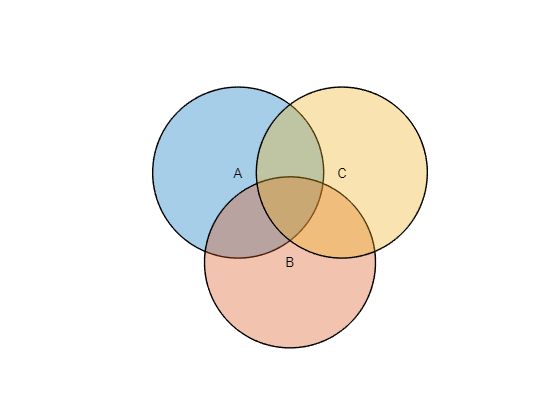

setListData = {[1 2 3]; [3 4 5]; [3 4 6]};
h = vennEulerDiagram(setListData, 'drawProportional', false, 'SetLabels', ["A"; "B"; "C"]);

Change the face colors, edge colors, and edge widths of the circles.

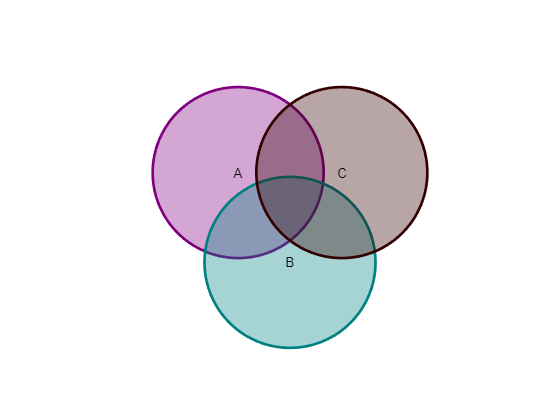

h.CircleFaceColors = [0.5 0 0.5; 0 0.5 0.5; 0.2 0 0];
h.CircleEdgeColors = [0.5 0 0.5; 0 0.5 0.5; 0.2 0 0];
h.CircleEdgeWidths = [2; 2; 2];

Color each disjoint intersection a different color. 

Note that for intersection colors and intersection transparencies, binary indexing is used to apply each color/transparency to its appropriate disjoint intersection. For instance, 3 in decimal corresponds to 11 in binary. Since there are 3 sets, we equivalently express this using 3 bits as 011. Each bit in this binary representation corresponds to a set, where the leftmost bit corresponds to the last set (set labeled "C") and the rightmost bit corresponds to the first set (set labeled "A"). The i-th bit from the right in the n-length padded binary representation, where n is the total number of sets, corresponds to whether or not the i-th set is included. So 011 does not include the set labeled "C", includes the set labeled "B", and includes the set labeled "A". In this way, we can convert any decimal number to a disjoint intersection of sets. Any row index for intersection colors or index for intersection transparencies is associated to a disjoint intersection using this method.

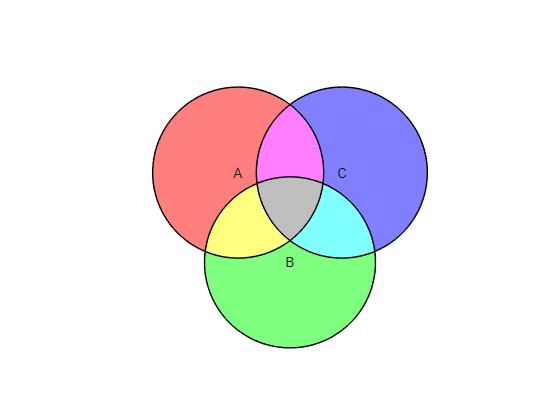

cmap = [1 0 0; % A
    0 1 0; % B
    1 1 0; % A & B
    0 0 1; % C
    1 0 1; % A & C
    0 1 1; % B & C
    0.5 0.5 0.5]; % A & B & C

tmap = 0.5 * ones(7, 1);
h.IntersectionColors = cmap;
h.IntersectionTransparencies = tmap;

## Proportional vennEulerDiagram using setListData

Create a proportional vennEulerDiagram by giving a cell array of vectors representing sets.

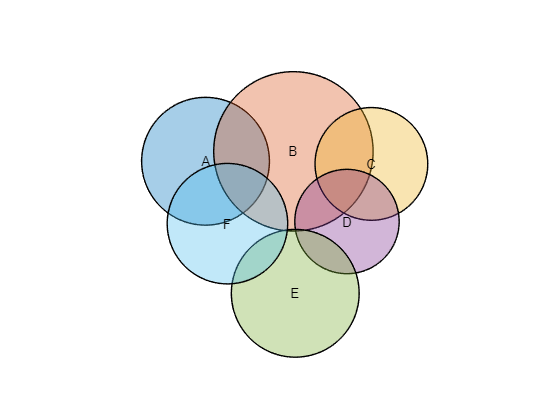

A = 1:9;
B = 7:20;
C = 18:24;
D = [17, 18, 24:27];
E = 27:35;
F = [5:7, 16, 35:38];
setListData = {A B C D E F};
setLabels = ["A"; "B"; "C"; "D"; "E"; "F"];
h = vennEulerDiagram(setListData, setLabels, 'drawProportional', true);

Show the counts and relative areas of each disjoint intersection.

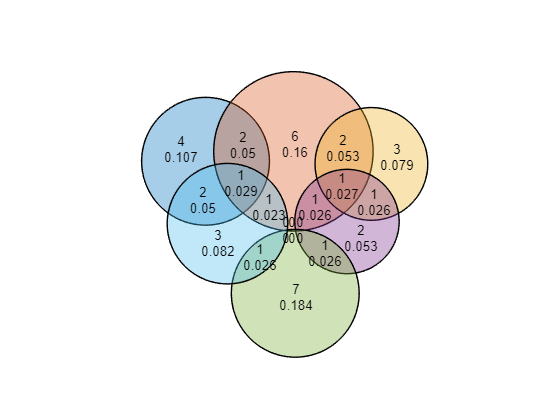

h.ShowIntersectionCounts = true;
h.ShowIntersectionAreas = true;
h.SetLabels = [];

Retreive the stress value for this visualization.

h.Stress

ans = 5.0255e-04

## Proportional vennEulerDiagram using setMembershipData

Create a proportional vennEulerDiagram by giving a 0-1 matrix denoting set membership of each element.

Note: This example takes a considerably longer time to run compared to the other examples in this file (typically up to a few minutes). Also note that "random" is a function from the Statistics and Machine Learning Toolbox.

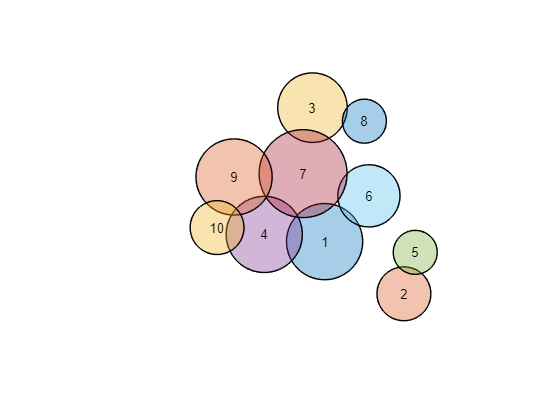

numElements = 50;
numSets = 10;
setMembershipData = random('Binomial', 1, 0.1, numElements, numSets);
h = vennEulerDiagram(setMembershipData, string(1:numSets), 'drawProportional', true);

Retrieve the stress value for this visualization. Note that the stress value will likely be higher than for the example above, which has somewhat nice intersection properties for this algorithm.

h.Stress

ans = 0.8697

## Proportional vennEulerDiagram using real data

Create a vennEulerDiagram for common and exclusively expressed genes of each group: shared epitope (SE), disease activity score 28 (DAS-28), treatment, and anti-cyclic citrullinated peptide (CCP) antibodies (Junta, Cristina Moraes et al. “Differential gene expression of peripheral blood mononuclear cells from rheumatoid arthritis patients may discriminate immunogenetic, pathogenic and treatment features.” *Immunology* vol. 127,3 (2009): 365-72. doi:10.1111/j.1365-2567.2008.03005.x).

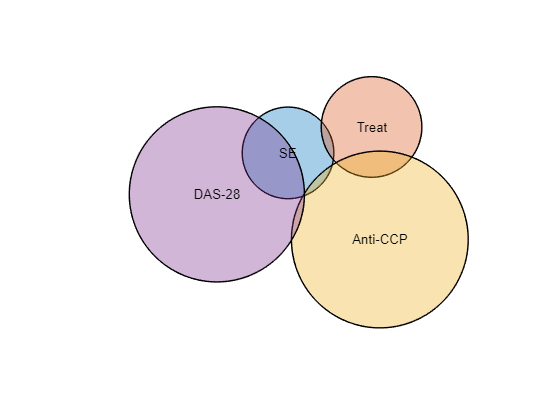

SE = 1:29;
Treat = [28, 30:63];
Anti_CCP = [29, 58:164];
DAS_28 = [14:27, 29, 165:255];
setListData = {SE, Treat, Anti_CCP, DAS_28};
setLabels = ["SE", "Treat", "Anti-CCP", "DAS-28"];
h = vennEulerDiagram(setListData, setLabels, 'drawProportional', true);